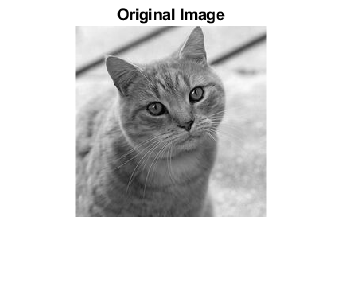

%% Image Interpolation Using Bicubic Interpolation Technique

g=imread("im004.jpg");
% by imread command we can read the image in the form of 2-D array.
g=im2gray(g);
% converting colour Image to grayscale image
[r c]=size(g);
% taking the size of image or array

t=[];
% creating an array which will be used as final outpout of image.

temp=1;
% first temperory variable for visiting array elements

gemp=1;
% second temperory variable for visiting array elements

for i=1:1:r

    for j=1:1:c

        t(temp,gemp)=g(i,j);  % Up sampling

        gemp=gemp+3;

    end

    temp=temp+3;

    gemp=1;

end

[R1 C1] = size(t);

for i=1:1:R1+4

     for j=1:1:4 

         t(i,C1+j)=0;

     end   

end 

for j=1:1:C1

     for i=1:1:2 

         t(R1+i,j)=0;

     end   

end


img_resized=uint8(t);
% storing the Upsampled image in new variable

figure;

imshow(g);
title('Original Image')
% displaying the Original Image

truesize

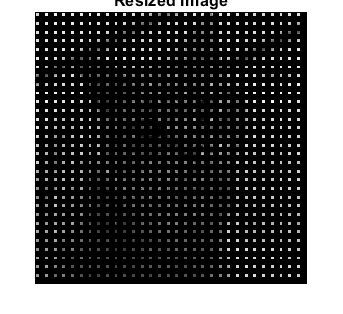


figure;

imshow(img_resized)
title('Resized Image')
% Displaying the Upsampled image

truesize

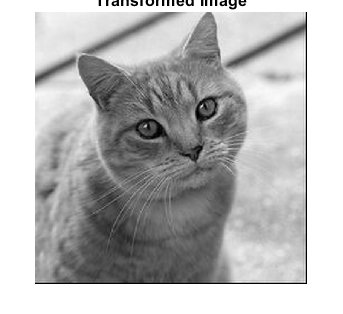


[R C] = size(t);

for i=1:3:R    % applying the Bicubic Interpolation Technique

    for j=1:9:C-2

       x=[j j+3 j+6 j+9];
       y=[t(i,j) t(i,j+3) t(i,j+6) t(i,j+9)];
       xx=j:1:(j+9);
       v=[];
       v=csapi(x,y,xx);
       t(i,j+1)=v(2);
       t(i,j+2)=v(3);
       t(i,j+4)=v(5);
       t(i,j+5)=v(6);
       t(i,j+7)=v(8);
       t(i,j+8)=v(9);
       
            


           

    end

end 

for j=1:1:C

    for i=1:9:R-2

       x=[i i+3 i+6 i+9];
       y=[t(i,j) t(i+3,j) t(i+6,j) t(i+9,j)];
       xx=i:1:(i+9);
       v=[];
       v=csapi(x,y,xx);
       t(i+1,j)=v(2);
       t(i+2,j)=v(3);
       t(i+4,j)=v(5);
       t(i+5,j)=v(6);
       t(i+7,j)=v(8);
       t(i+8,j)=v(9);
       
            


           

    end

end 

img_resized1=uint8(t);



figure;

imshow(img_resized1)
title('Transformed Image')
% Displaying the Tranformed image


truesize